# Thermoeconomic Diagnosis Demo

Use ThermoeconomicDiagnosis function to compare two states of the plant ans make diagnosis

#### Select and check the model file

file="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\orcvcr\orcvcr_model.json";
data=ReadDataModel(file);

#### Select the parameters

States=convertCharsToStrings(data.getStateNames);
State=convertStringsToChars(States(6));
DiagnosisMethod='WASTE_INTERNAL';

#### Compute Diagnosis Analysis

res=ThermoeconomicDiagnosis(data,'State',State,'DiagnosisMethod',DiagnosisMethod,'Show',true);

Fuel Impact:   410.000 (kW)
Malfunction Cost:   -58.445 (kW)

Diagnosis Summary

Key        MF(kW)     ΔI(kW)    ΔPt(kW)    MF*(kW)    MR*(kW)   ΔPt*(kW)
—————————————————————————————————————————————————————————————————————————
BLR        -0.308    119.900      0.000     -0.308     -9.431      0.000
TRB         0.170     51.700      0.000      0.217     -7.581      0.000
PMP         0.037      1.930      0.000      0.067     -0.110      0.000
CMP         0.000      0.000      0.000      0.000      2.720      0.000
EVAP        0.000      0.000      0.000      0.000      0.000      0.000
GEN         0.013      4.370    200.000      0.023     -0.158    437.482
VEXP        0.000      0.000      0.000      0.000      0.000      0.000
CND        -0.037     32.100      0.000     -6.500     -6.421      0.000
ENV        -0.127    210.000    200.000     -6.502    -20.980    437.482


Malfunction Table (kW)

                BLR       TRB       PMP       CMP      EVAP       GEN      VEXP       CND

#### Show Results

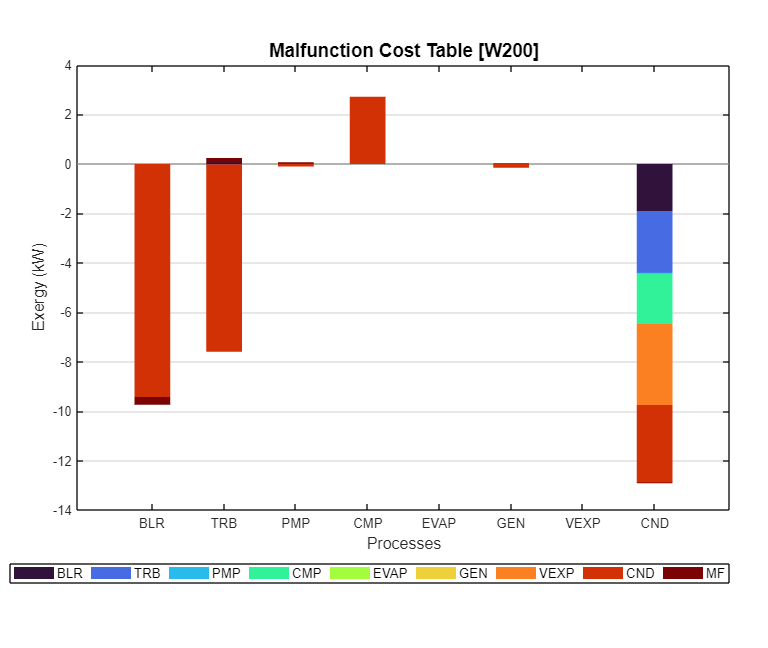

showGraph(res,'mfc',false);

#### Total Malfunction Cost Analysis

tmfc=TotalMalfunctionCost(res);

Fuel Impact:   410.000 (kW)
Malfunction Cost:   -58.445 (kW)

Total Malfunction Cost (kW)

 Key            MF*        MR*       MPt*      Total
—————————————————————————————————————————————————————
 BLR         -0.308     -9.431      0.000     -9.740
 TRB          0.217     -7.581      0.000     -7.364
 PMP          0.067     -0.110      0.000     -0.043
 CMP          0.000      2.720      0.000      2.720
 EVAP         0.000      0.000      0.000      0.000
 GEN          0.023     -0.158    -30.963    -31.098
 VEXP         0.000      0.000      0.000      0.000
 CND         -6.500     -6.421      0.000    -12.921
 ENV         -6.502    -20.980    -30.963    -58.445

